## Example: Finding the max/min using Mixed-Integer Linear Programming

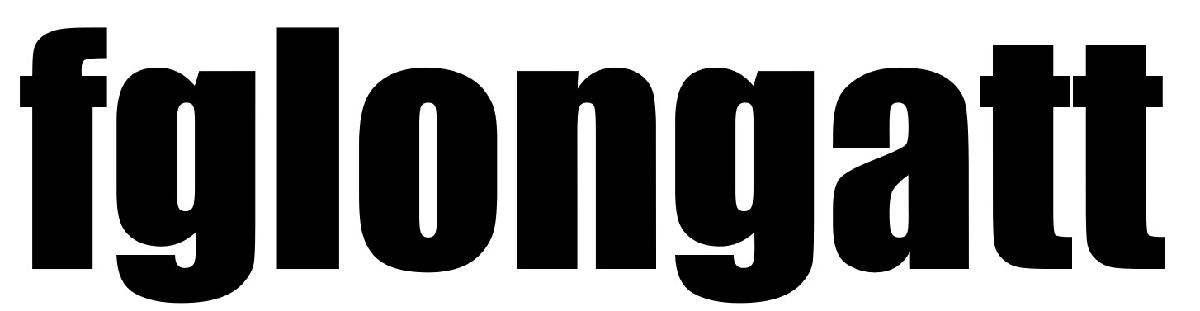  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

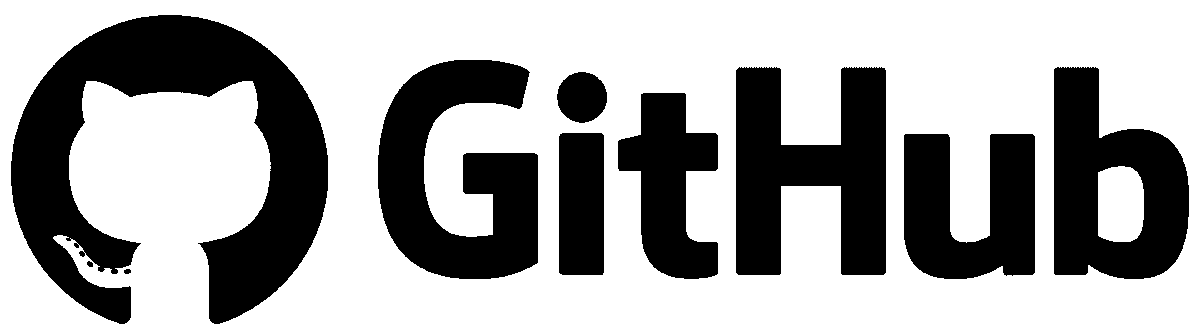 [https://github.com/fglongatt](https://github.com/fglongatt) 

Consider the following global optimisation problem:


$$\min \left\lbrack {-x}_1 {-2x}_2 \right\rbrack$$


$x_1 \in \left\lbrack 0,100\right\rbrack$     Continous

$x_2 \in \left\lbrace 1,2,3,4,5\right\rbrace$    Discrete

Subject:


$$x_1 +{4x}_2 \le 20$$



$$x_1 +x_2 =10$$


**Step 1:** Defining the onective function

f = [-1;-2];
intcon = 2;

**Step 2: **Defining matrix and vector of ***the inequality constraints***:

A =  [1, 4]

A =      1     4


b = [20]

b = 20

**Step 3: **Defining matrix and vector of ***the equality constraints***:

Aeq = [1,1];
beq = [10];

**Step 4: **Defining vector of **the upper and lower boundaries**:

lb = [0;1];
ub = [100;5]; 

**Step 5: **Executing the optimization

Mixed-integer linear programming (MILP):

[x,fval,exitflag,output] = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub)

LP:                Optimal objective value is -13.000000.                                           


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0. The intcon variables are integer within tolerance, options.IntegerTolerance = 1e-05.



x =      7
     3


fval = -13

exitflag = 1

output = struct with fields:
        relativegap: 0
        absolutegap: 0
      numfeaspoints: 1
           numnodes: 0
    constrviolation: 0
            message: 'Optimal solution found.↵↵Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 0. The intcon variables are integer within tolerance, options.IntegerTolerance = 1e-05.'


x

x =      7
     3
